clear
clc

k = 0:0.01:50;
num = [1 1];
den = [conv([1 -1 0],[1 4 16])];
[r,k] = rlocus(num,den,k);
kn = [];

for j = 1:1:5001
    if(all(real(r(j,:))<0))
        kn = [[kn];j];
        sk = 0.01*(kn-1);
    end
end
r1 = min(sk)

r1 = 23.3200

r2 = max(sk)

r2 = 35.6800

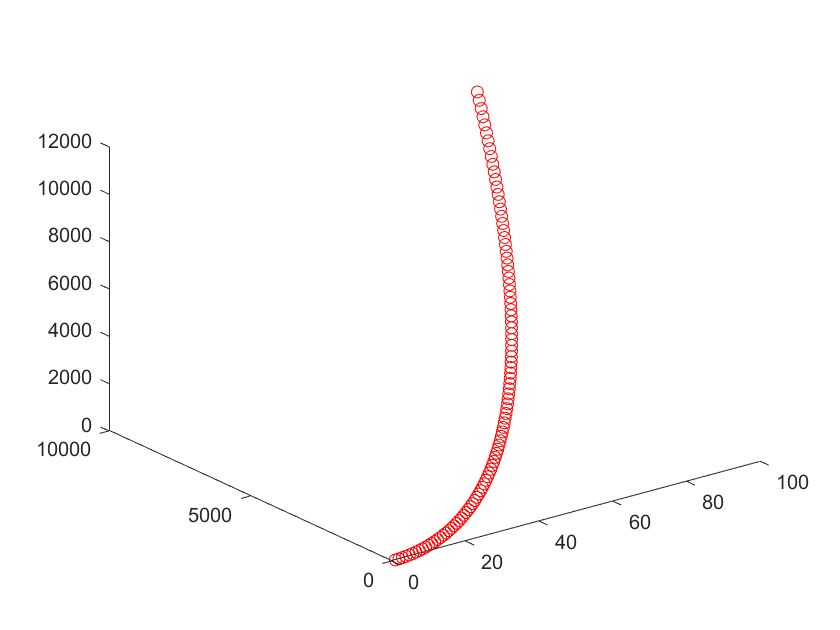

clear
clc

x = [1:1:100];
y = x.^2;
z = x+y;
plot3(x,y,z,'ro')

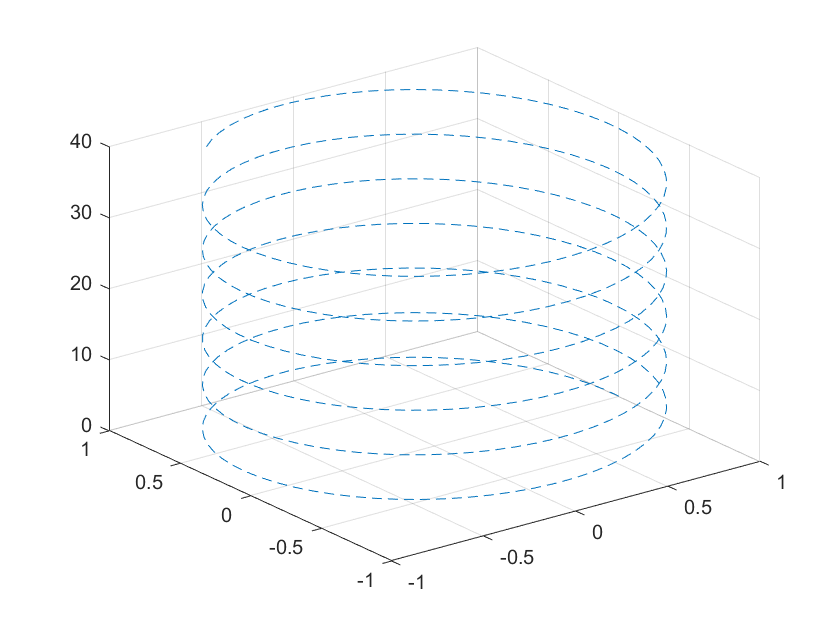


z = [0:0.1:40];
x = cos(z);
y = sin(z);
plot3(x,y,z,'--')
grid on;

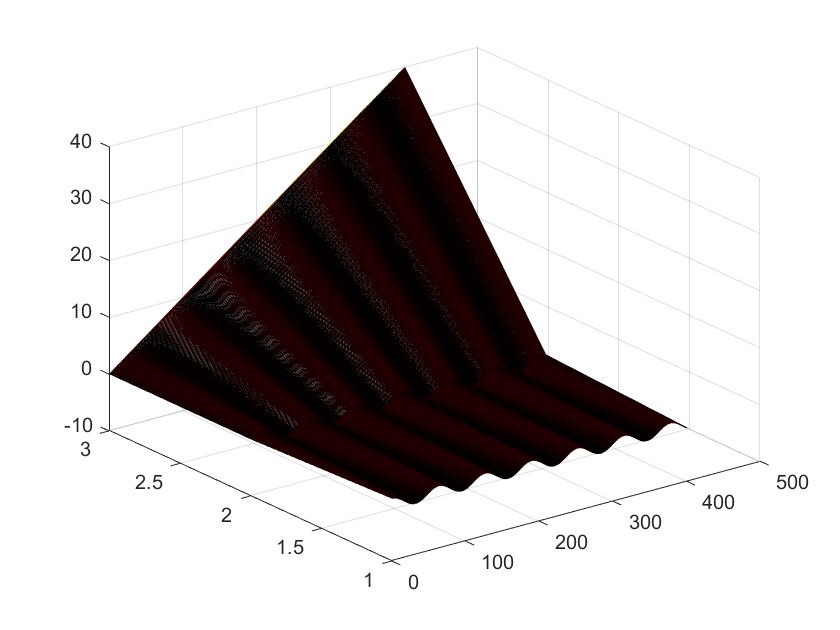


z =[x;y;z];
mesh(z)

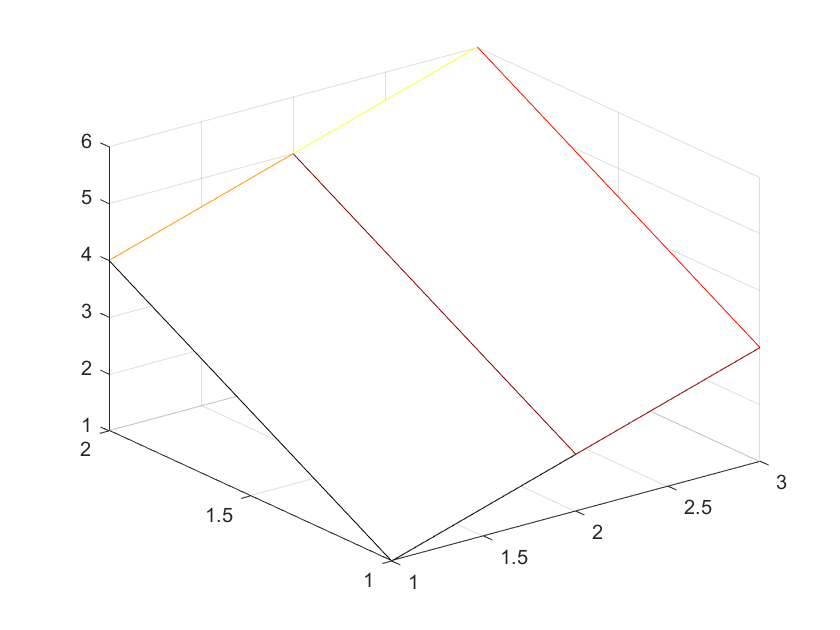


Z = [1 2 3; 4 5 6];
mesh(Z)

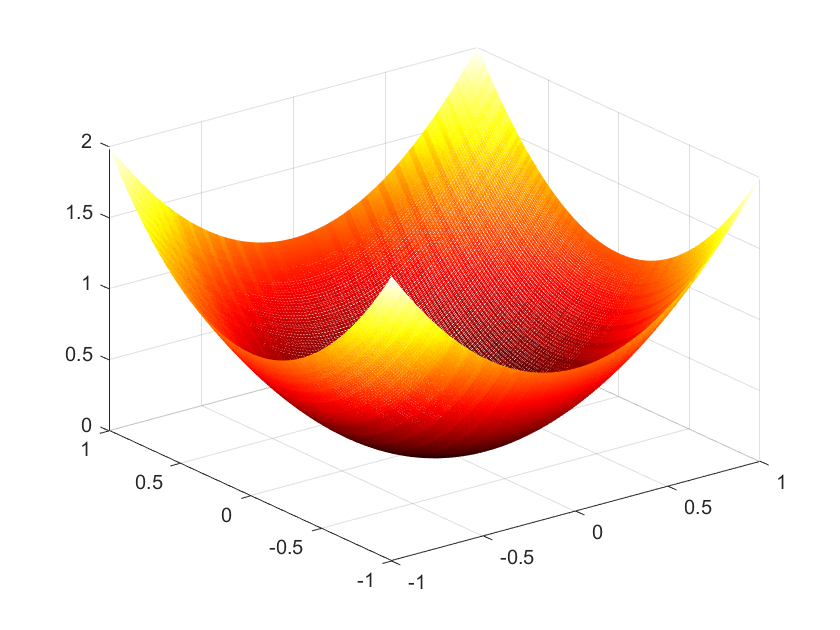


[x,y]=meshgrid(x,y);
z = x.^2+y.^2;
mesh(x,y,z)

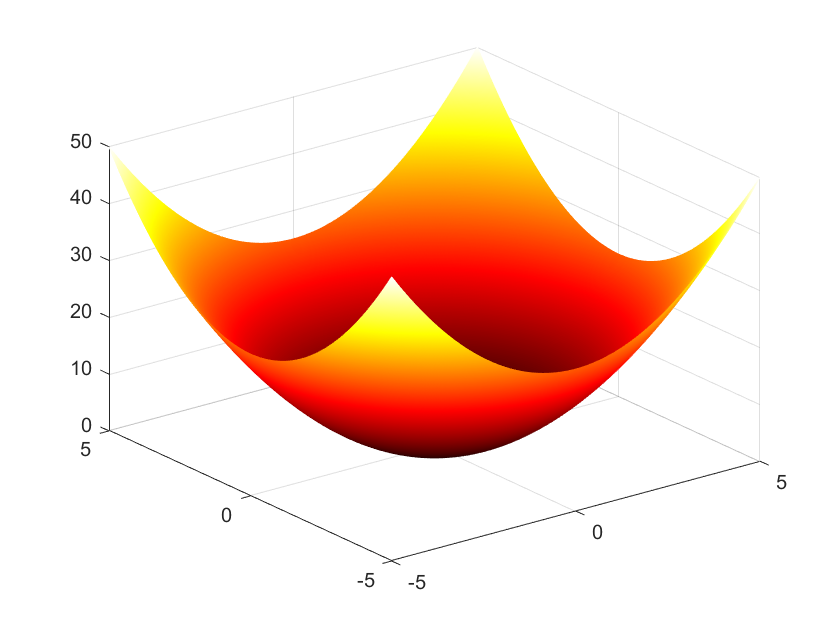


x = -5:0.01:5;
y = x;
[x,y] = meshgrid(x,y);
z = x.^2+y.^2;
mesh(x,y,z)

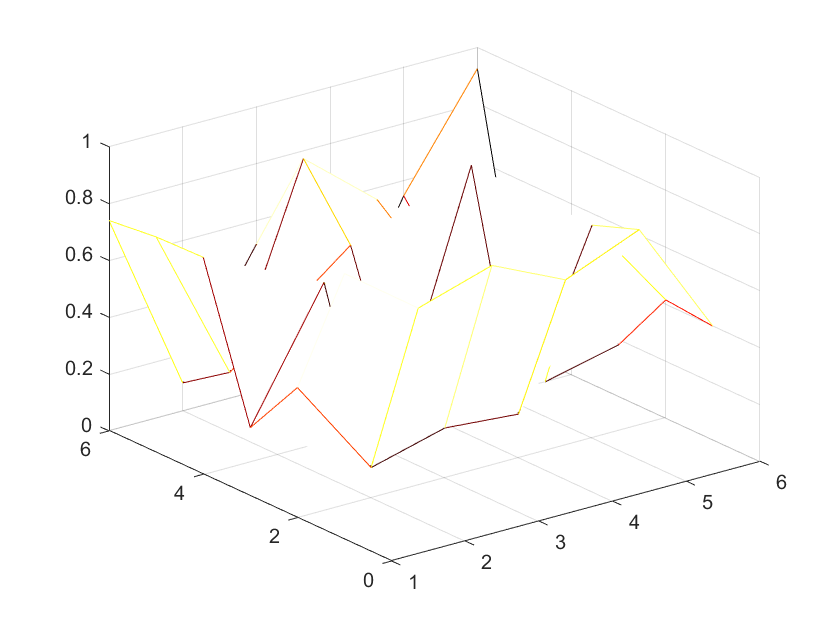


z = rand(6,6);
mesh(z)

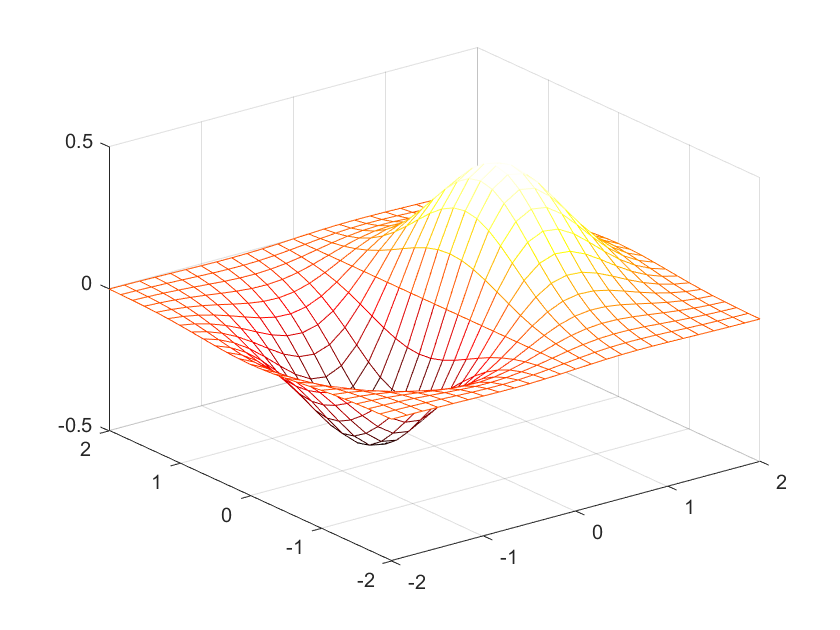


x = linspace(-2,2,25);
y = x;
[x,y] = meshgrid(x,y);
z = x.*exp(-x.^2-y.^2);
mesh(x,y,z)

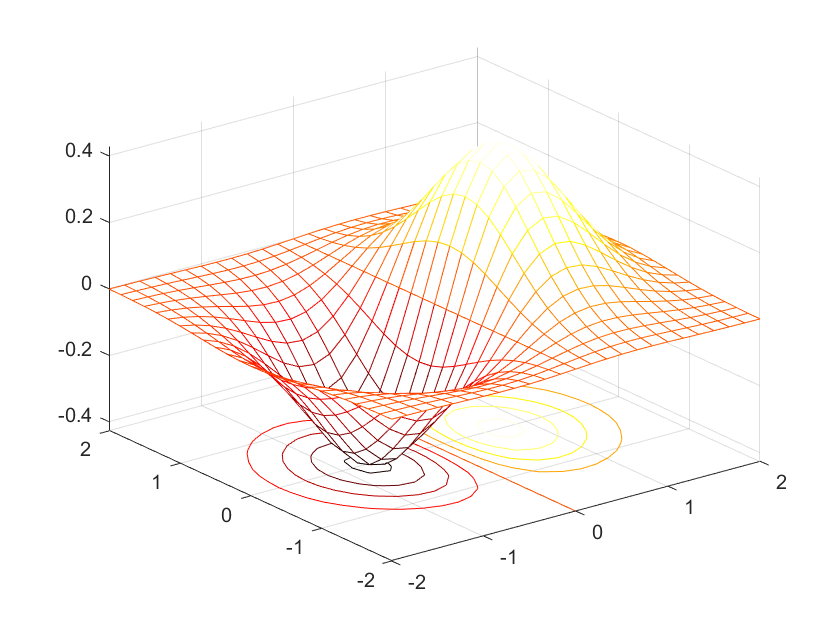


meshc(x,y,z)

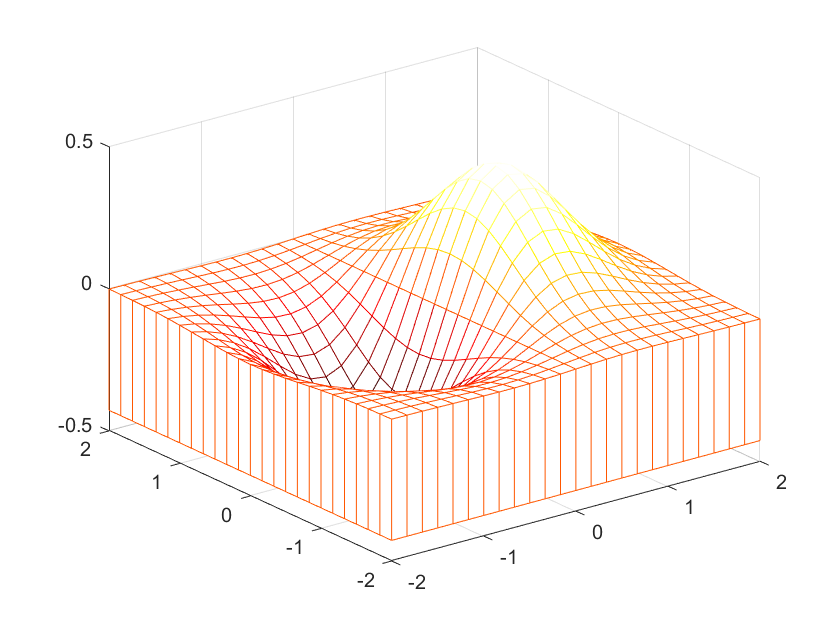

meshz(x,y,z)

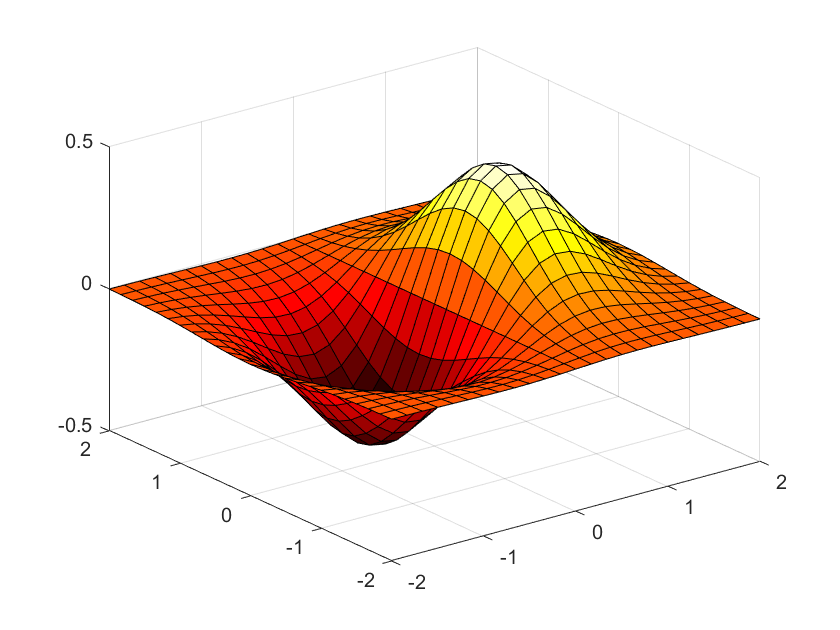


surf(x,y,z)

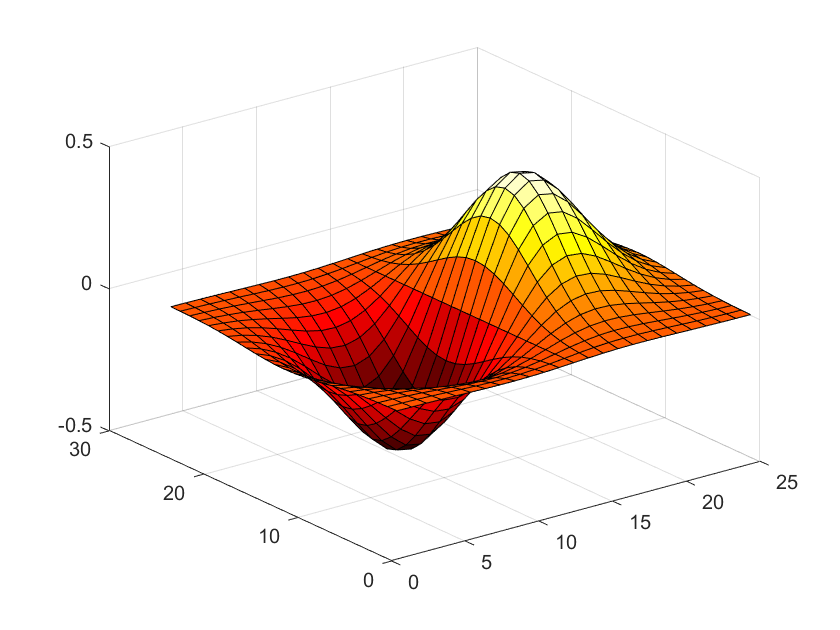

surf(z)

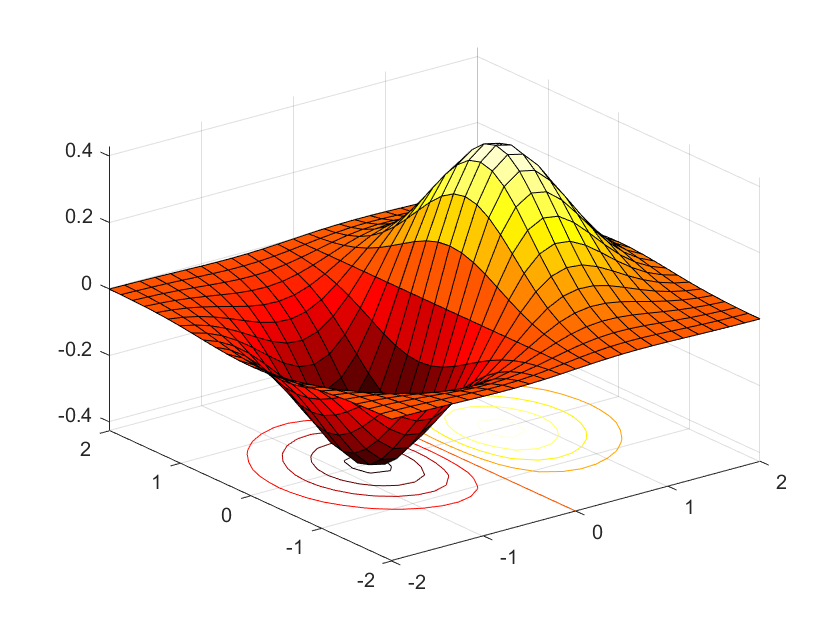


surfc(x,y,z)

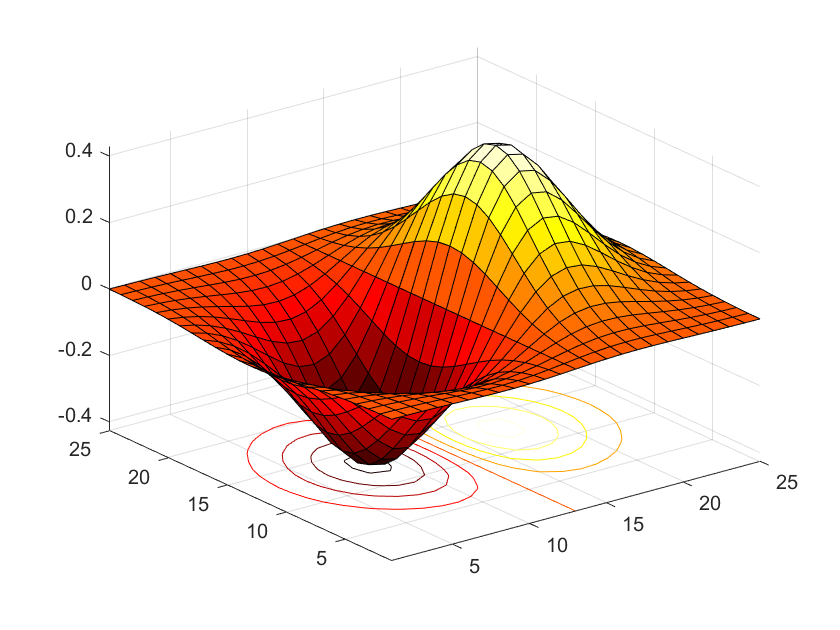

surfc(z)

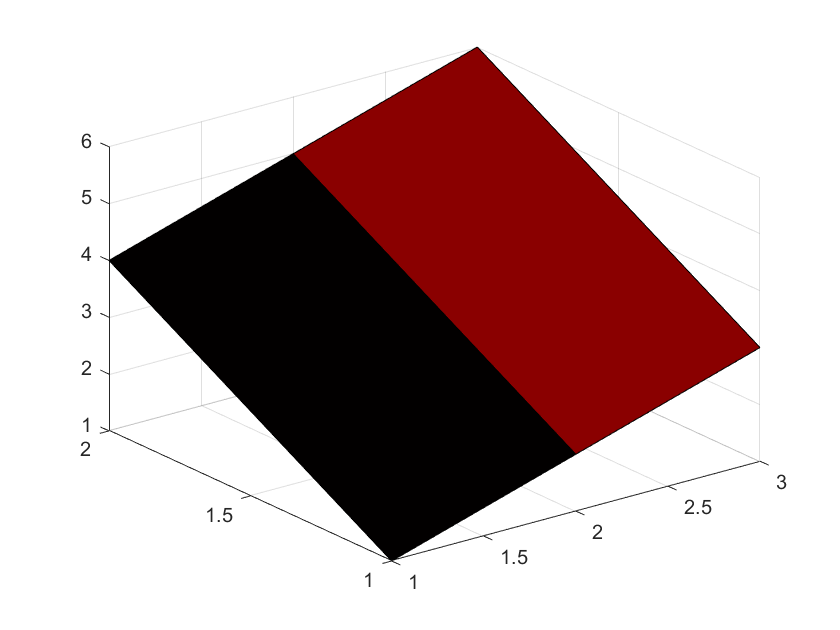


z=[1 2 3; 4 5 6];
surf(z)


z=rand(6,6)

z =     0.6537    0.4400    0.6712    0.3174    0.9509    0.9970
    0.9326    0.2576    0.7152    0.8145    0.4440    0.2242
    0.1635    0.7519    0.6421    0.7891    0.0600    0.6525
    0.9211    0.2287    0.4190    0.8523    0.8667    0.6050
    0.7947    0.0642    0.3908    0.5056    0.6312    0.3872
    0.5774    0.7673    0.8161    0.6357    0.3551    0.1422


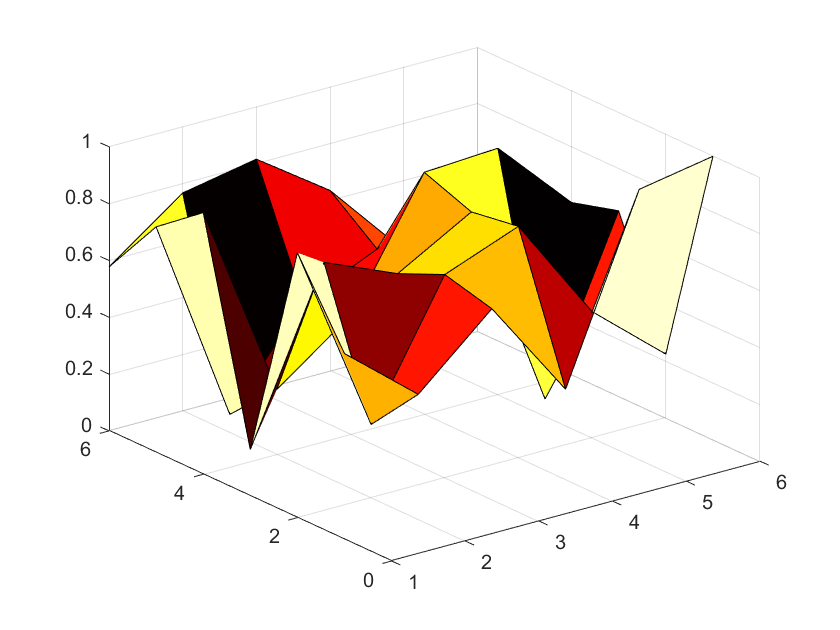

surf(z)


figure(1)
a = peaks(20);
h = surf(a)

h =   Surface - 属性:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20]
           YData: [20×1 double]
           ZData: [20×20 double]
           CData: [20×20 double]

  显示 所有属性


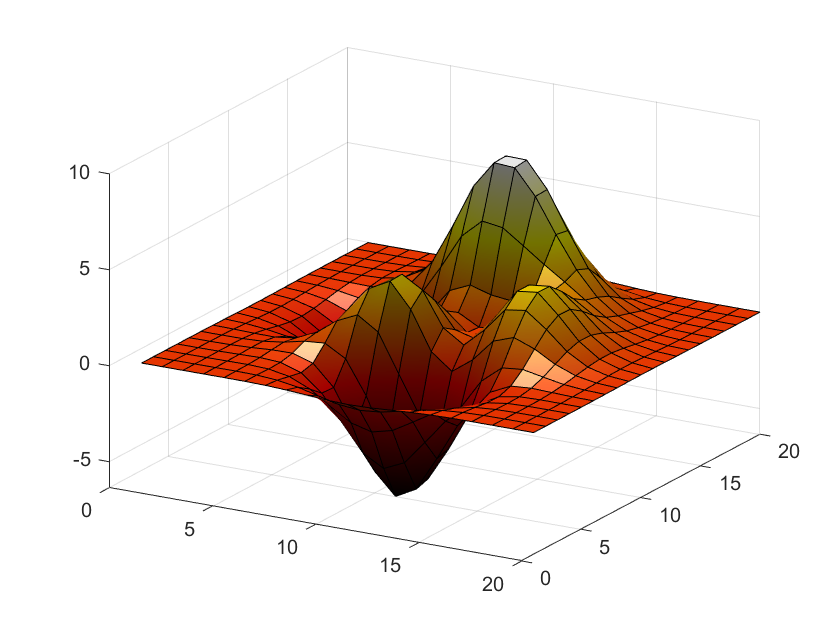

colormap hot
shading interp
set(h,'EdgeColor','k')
light('Position',[-2,2,20])
view([30 25])

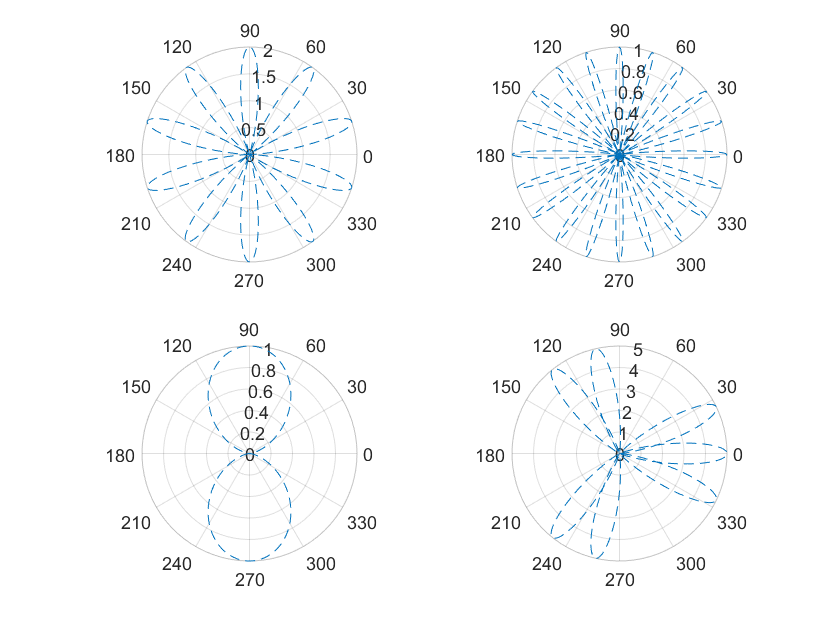

clear
clc

theta = [-pi:0.01:pi];
rho(1,:)=2*sin(5*theta).^2;
rho(2,:)=cos(10*theta).^3;
rho(3,:)=sin(theta).^2;
rho(4,:)= 5*cos((3.5)*theta).^3;
for k = 1:4
    subplot(2,2,k)
    polarplot(theta,rho(k,:),'--')
    % grid on
end

disp('程序结束')

程序结束


clear
clc

y = mean([1:100])

y = 50.5000

help mean

mean - 数组的均值

    此 MATLAB 函数 返回 A 沿大小不等于 1 的第一个数组维度的元素的均值。

    M = mean(A)
    M = mean(A,'all')
    M = mean(A,dim)
    M = mean(A,vecdim)
    M = mean(___,outtype)
    M = mean(___,nanflag)

    另请参阅 <a href="https://localhost:31515/static/help/matlab/ref/median.html">median</a>, <a href="https://localhost:31515/static/help/matlab/ref/mode.html">mode</a>, <a href="https://localhost:31515/static/help/matlab/ref/std.html">std</a>, <a href="https://localhost:31515/static/help/matlab/ref/sum.html">sum</a>, <a href="https://localhost:31515/static/help/matlab/ref/var.html">var</a>

    mean 的文档
    名为 mean 的其他函数




x = [1:0.1:100];
sum(x)

ans = 5.0046e+04

size(x)

ans =      1   991


length(x)

ans = 991


std(x)

ans = 28.6221

mean(x)

ans = 50.5000

rank(x)

ans = 1


A = [1 2 3;4 5 6]

A =      1     2     3
     4     5     6


std(A)

ans =     2.1213    2.1213    2.1213


mean(A)

ans =     2.5000    3.5000    4.5000


rank(A)

ans = 2

clear
clc

for n = 1:10
    y(n) = sin(n*pi/10);
    if n == 5
        break
    end
end

n = 1:10;
x = sin(n*pi/10);

EPS = 1;
num = 0;
while (1+EPS>1)
    EPS = EPS/2;
    num=num+1;
end
num

num = 53

EPS

EPS = 1.1102e-16


EPS =1;
for num=1:100
    EPS = EPS/2;
    if(1+EPS)<=1
        break;
    end
end
EPS

EPS = 1.1102e-16


apples = 200;
cost = apples*2.5;
if((apples>50)&&(apples<=100))
    cost = 0.8*cost;
elseif(apples>100)
    cost = 0.7*cost
end

cost = 350

clear
clc

eps

ans = 2.2204e-16

clear
clc

G1 = tf([1 1],[1 2 1])

G1 =
 
      s + 1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



G2 = zpk([-1],[-1 -1],[1])

G2 =
 
   (s+1)
  -------
  (s+1)^2
 
Continuous-time zero/pole/gain model.



[num,den] = tfdata(G1)

num = 1×1 cell 数组
    {1×3 double}


den = 1×1 cell 数组
    {1×3 double}


[z,p,k] = zpkdata(G2)

z = 1×1 cell 数组
    {[-1]}


p = 1×1 cell 数组
    {2×1 double}


k = 1

[num1,den1]= zp2tf([-1],[-1 -1],[1])

num1 =      0     1     1


den1 =      1     2     1


[z1,p1,k1] = tf2zpk([1 1],[1 2 1])

z1 =      0
    -1


p1 =     -1
    -1


k1 = 1

[a,b,c,d] = zp2ss([-1],[-1 -1],[1])

a =     -2    -1
     1     0


b =      1
     0


c =      1     1


d = 0


A = [0 1;-2 -3];
B = [1 0;0 1];
C = [1 0];
D = [0 0];
[num2,den2] = ss2tf(A,B,C,D,1)

num2 =      0     1     3


den2 =      1     3     2


[num3,den3] = ss2tf(A,B,C,D,2)

num3 =      0     0     1


den3 =      1     3     2


G6 = tf(num2,den2)

G6 =
 
      s + 3
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



G7 = tf(num3,den3)

G7 =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.




A2 = [0 1;-25 -4];
B2 = [1 1 ;0 1];
C2 = [1 0;0 1];
D2 = [0 0 ;0 0];

[num4,den4] = ss2tf(A2,B2,C2,D2,1)

num4 =      0     1     4
     0     0   -25


den4 =     1.0000    4.0000   25.0000


[num5,den5] = ss2tf(A2,B2,C2,D2,2)

num5 =          0    1.0000    5.0000
         0    1.0000  -25.0000


den5 =     1.0000    4.0000   25.0000




[z p k]=ss2zp(A2,B2,C2,D2,1)

z =     -4   Inf


p =   -2.0000 + 4.5826i
  -2.0000 - 4.5826i


k =      1
   -25


residue(num2,den2)

ans =     -1
     2




G = zpk([-3],[-1 -2 -5],[6])

G =
 
       6 (s+3)
  -----------------
  (s+1) (s+2) (s+5)
 
Continuous-time zero/pole/gain model.



[num10,den10]=zp2tf([-3],[-1 -2 -5],[6])

num10 =      0     0     6    18


den10 =      1     8    17    10


G10 = tf(num10,den10)

G10 =
 
         6 s + 18
  -----------------------
  s^3 + 8 s^2 + 17 s + 10
 
Continuous-time transfer function.



[A B C D] = zp2ss([-3],[-1 -2 -5],[6])

A =    -1.0000         0         0
    2.0000   -7.0000   -3.1623
         0    3.1623         0


B =      1
     1
     0


C =          0         0    1.8974


D = 0

clear
clc
